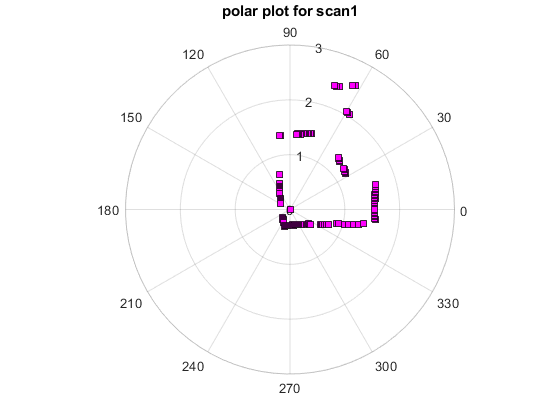

% prob 6

%load data
data = load('rall2.mat');
r_all = data.r_all;
t1 = r_all(:,1);
t1t = [1:1:360]';
t2 = r_all(:,2);
t2t = [1:1:360]';
t3 = r_all(:,3);
t3t = [1:1:360]';
t4 = r_all(:,4);
t4t = [1:1:360]';
t5 = r_all(:,5);
t5t = [1:1:360]';
t6 = r_all(:,6);
t6t = [1:1:360]';

%clean the data
% t1_rc = nonzeros(t1);
% t2_rc = nonzeros(t2);
% t3_rc = nonzeros(t3);
% t4_rc = nonzeros(t4);

% plot to confirm data quality
figure()
polarplot(t1,'ks',...
    'MarkerSize',6,'MarkerFaceColor','m')
title('polar plot for scan1')


% transform to global
% phi
t1l = [t1 .* cosd(t1t), t1 .* sind(t1t), ones(360,1)];
d = 0.1143 %meters

d = 0.1143

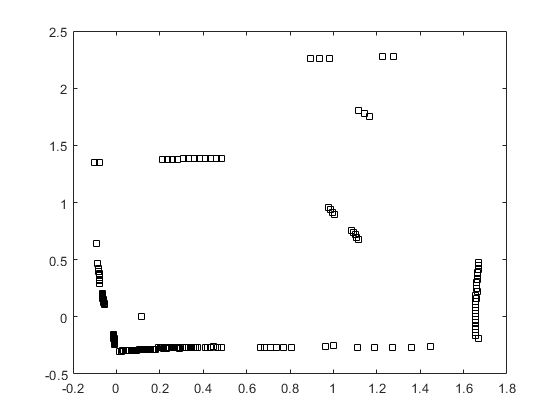

t1n = [1 0 d; 0 1 0; 0 0 1] * t1l';
xn = 0;
yn = 0;
phi = 0;
t1g = [1 0 xn; 0 1 yn; 0 0 1] * [cosd(0),-sind(0),0;sind(0),cosd(0),0;0,0,1] * t1n;
figure()
plot(t1g(1,:),t1g(2,:),'ks')

t2l = [t2 .* cosd(t2t), t2 .* sind(t2t), ones(360,1)];
d = 0.1143 %meters

d = 0.1143

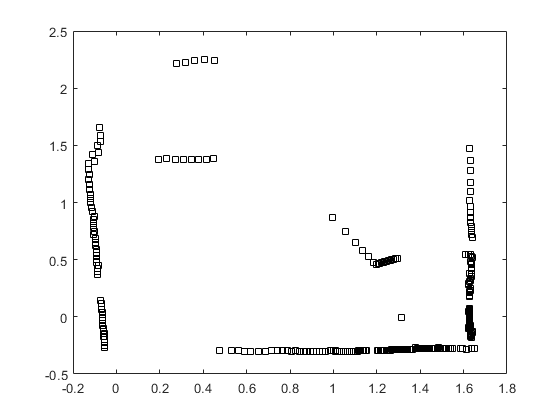

t2n = [1 0 d; 0 1 0; 0 0 1] * t2l';
xn = 1.2;
yn = 0;
phi = -3;
t2g = [1 0 xn; 0 1 yn; 0 0 1] * [cosd(phi),-sind(phi),0;sind(phi),cosd(phi),0;0,0,1] * t2n;
figure()
plot(t2g(1,:),t2g(2,:),'ks')

t3l = [t3 .* cosd(t3t), t3 .* sind(t3t), ones(360,1)];
d = 0.1143 %meters

d = 0.1143

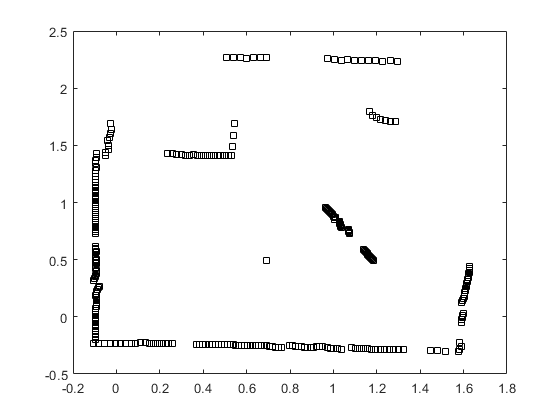

t3n = [1 0 d; 0 1 0; 0 0 1] * t3l';
xn = 0.58;
yn = 0.5;
phi = -5;
t3g = [1 0 xn; 0 1 yn; 0 0 1] * [cosd(phi),-sind(phi),0;sind(phi),cosd(phi),0;0,0,1] * t3n;
figure()
plot(t3g(1,:),t3g(2,:),'ks')

t4l = [t4 .* cosd(t4t), t4 .* sind(t4t), ones(360,1)];
d = 0.1143 %meters

d = 0.1143

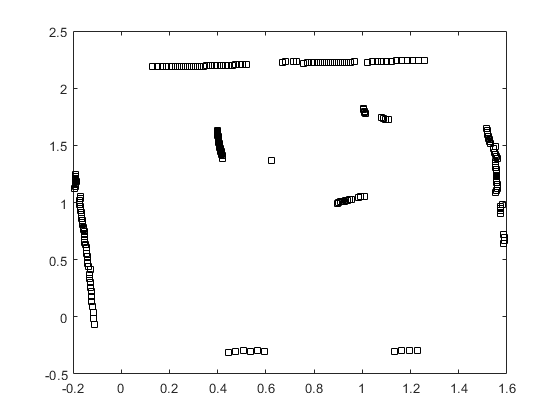

t4n = [1 0 d; 0 1 0; 0 0 1] * t4l';
xn = 0.508;
yn = 1.3716;
phi = 0;
t4g = [1 0 xn; 0 1 yn; 0 0 1] * [cosd(phi),-sind(phi),0;sind(phi),cosd(phi),0;0,0,1] * t4n;
figure()
plot(t4g(1,:),t4g(2,:),'ks')

t5l = [t5 .* cosd(t5t), t5 .* sind(t5t), ones(360,1)];
d = 0.1143 %meters

d = 0.1143

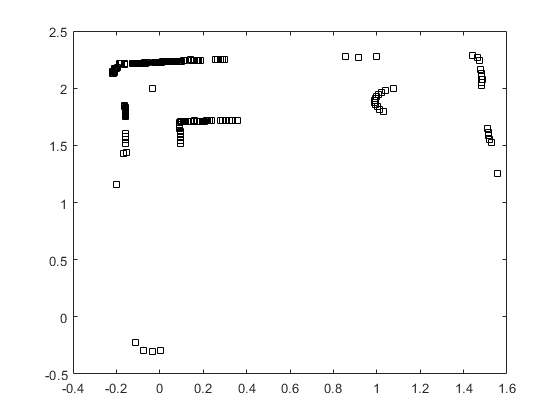

t5n = [1 0 d; 0 1 0; 0 0 1] * t5l';
xn = -0.15;
yn = 2;
phi = 0;
t5g = [1 0 xn; 0 1 yn; 0 0 1] * [cosd(phi),-sind(phi),0;sind(phi),cosd(phi),0;0,0,1] * t5n;
figure()
plot(t5g(1,:),t5g(2,:),'ks')

t6l = [t6 .* cosd(t6t), t6 .* sind(t6t), ones(360,1)];
d = 0.1143 %meters

d = 0.1143

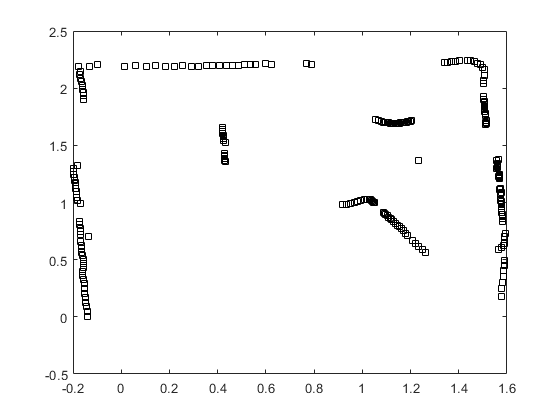

t6n = [1 0 d; 0 1 0; 0 0 1] * t6l';
xn = 1.12;
yn = 1.3716;
phi = 0;
t6g = [1 0 xn; 0 1 yn; 0 0 1] * [cosd(phi),-sind(phi),0;sind(phi),cosd(phi),0;0,0,1] * t6n;
figure()
plot(t6g(1,:),t6g(2,:),'ks')

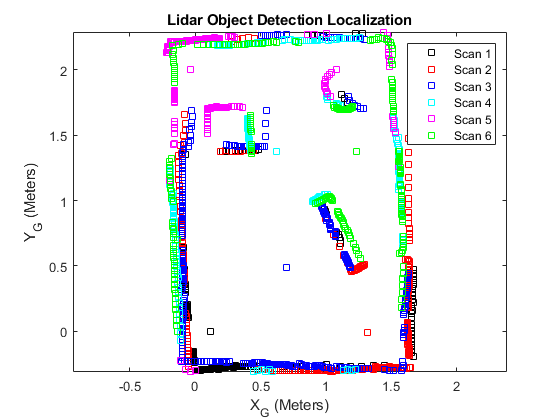

figure()
plot(t1g(1,:),t1g(2,:),'ks'), hold on
plot(t2g(1,:),t2g(2,:),'rs')
plot(t3g(1,:),t3g(2,:),'bs')
plot(t4g(1,:),t4g(2,:),'cs')
plot(t5g(1,:),t5g(2,:),'ms')
plot(t6g(1,:),t6g(2,:),'gs')
xlabel('X_{G} (Meters)')
ylabel('Y_{G} (Meters)')
title('Lidar Object Detection Localization')
legend('Scan 1','Scan 2', 'Scan 3', 'Scan 4', 'Scan 5', 'Scan 6')
axis equal